# Reto 3

% Definimos variables importantes
clear all; clc
global M N w
N = 100;       % Numero de agentes
M = 10000;  % Cantidad de dinero
w = [1 9]; % Intervalo de salarios
V = 0;          % Valor inicial del mercado
% Se asigna M/N monedas a cada agente inicialmente
for ii = 1:N
    agentes(ii) = Agente(ii,M/N);
end
global agentes

years = 1;
counter = 1;
% Simulacion de varios years
for vv = 1:years
    % Simulacion de un Year
    for yy = 1:12
        % Simulacion de un Mes
        for tt = 1:N
            % Regla de seleccion de agente
            a = randi(N);
            
            % Regla de contratacion
            if agentes(a).clase == 'U'
                % Conjunto de potenciales empleadores
                H = agentes(([agentes.clase] == 'U' | [agentes.clase] == 'C' & [agentes.id] ~= a));
                % Seleccionar un empleador del conjunto H
                f = @(c,H) H(c).m / sum([H.m]);
                P = rand;
                CDF = 0;
                for cc = 1:length(H)
                    CDF = CDF + f(cc,H);
                    if CDF > P
                        break
                    end
                end
                
                % Realizar contratacion si es posible
                if H(cc).m > sum(w)/2
                    agentes(a).e = H(cc).id;
                    agentes(H(cc).id).e_x = [agentes(H(cc).id).e_x, a];
                end
            end
            
            % Regla de gastos
            % Seleccionar un agente aleatorio distinto de a
            b = a;
            while b == a
                b = randi(N);
            end
            % Seleccionar una cantidad a gastar en el intervalo [0,m_b]
            m = randi(agentes(b).m + 1) - 1;
            % Transferir el dinero m del agente b al mercado (V)
            agentes(b).m = agentes(b).m - m;
            V = V + m;
            
            % Regla de ingresos del mercado
            if agentes(a).clase ~= 'U'
                % Seleccionar una cantidad m del mercado
                m = randi(V + 1) - 1;
                V = V - m; % Retirar m del mercado
                % Transferir dinero
                if agentes(a).clase == 'E'
                    agentes(agentes(a).e).m = agentes(agentes(a).e).m + m;
                    agentes(agentes(a).e).flujoDinero = agentes(agentes(a).e).flujoDinero + m;
                else
                    agentes(a).m = agentes(a).m + m;
                    agentes(a).flujoDinero = agentes(a).flujoDinero + m;
                end
            end
            
            % Regla de despidos
            if agentes(a).clase == 'C'
                % Determinar el numero de despidos
                u = ceil(length(agentes(a).e_x) - (agentes(a).m/(sum(w)/2)));
                
                for ii = 1:u
                    % Seleccionar aleatoriamente al agente despedido
                    despedido = randi(length(agentes(a).e_x));
                    % Despedir al agente
                    agentes(agentes(a).e_x(despedido)).e = 0;
                    agentes(a).e_x(despedido) = [];
                end
            end
            
            % Regla de pagos
            for ii = agentes(a).e_x
                w_pago = randi(w);
                if agentes(a).m - w_pago >= 0
                    agentes(ii).m = agentes(ii).m + w_pago;
                    agentes(ii).flujoDinero = agentes(ii).flujoDinero + w_pago;
                    agentes(a).m = agentes(a).m - w_pago;
                else
                    w_pago = randi([0,agentes(a).m]);
                    agentes(ii).m = agentes(ii).m + w_pago;
                    agentes(ii).flujoDinero = agentes(ii).flujoDinero + w_pago;
                    agentes(a).m = agentes(a).m - w_pago;
                end
            end
            
            % Guardar datos en el tiempo
            agentes_t(:,counter) = [agentes];
            counter = counter + 1;
            
        end
    end
end

## Gráficas

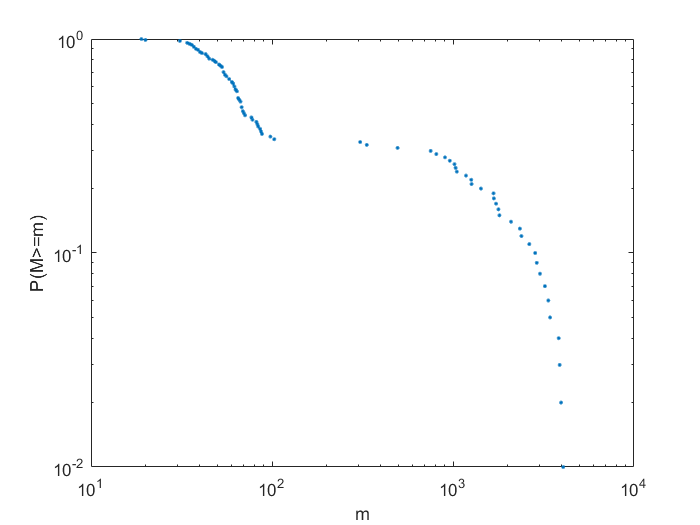

for ii = 1:N
    y(ii) = length(agentes([agentes.flujoDinero] >= agentes(ii).flujoDinero))/N;
end
plot([agentes.flujoDinero],y,'.')
xlabel('m')
ylabel('P(M>=m)')
set(gca,'xscale','log')
set(gca,'yscale','log')

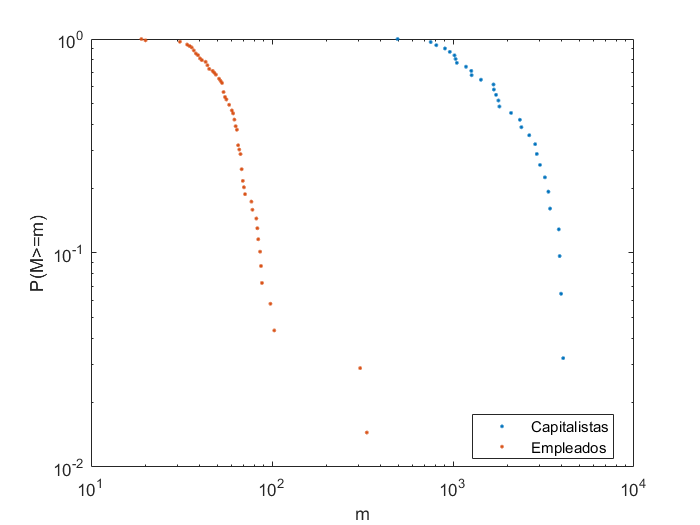

C = agentes([agentes.clase] == 'C');
for ii = 1:length(C)
    y_C(ii) = length(C([C.flujoDinero] >= C(ii).flujoDinero))/length(C);
end
E = agentes([agentes.clase] == 'E');
for ii = 1:length(E)
    y_E(ii) = length(E([E.flujoDinero] >= E(ii).flujoDinero))/length(E);
end
plot([C.flujoDinero],y_C,'.',[E.flujoDinero],y_E,'.')
legend({'Capitalistas','Empleados'},"Location","best")
xlabel('m')
ylabel('P(M>=m)')
set(gca,'xscale','log')
set(gca,'yscale','log')

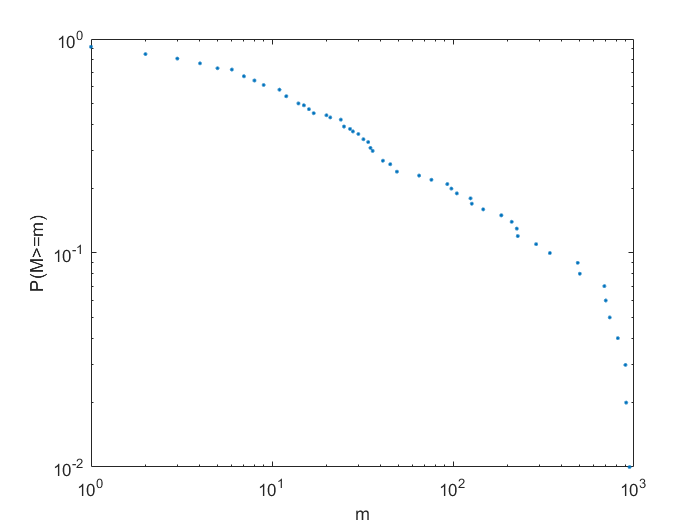

for ii = 1:N
    y(ii) = length(agentes([agentes.m] >= agentes(ii).m))/N;
end
plot([agentes.m],y,'.')
xlabel('m')
ylabel('P(M>=m)')
set(gca,'xscale','log')
set(gca,'yscale','log')

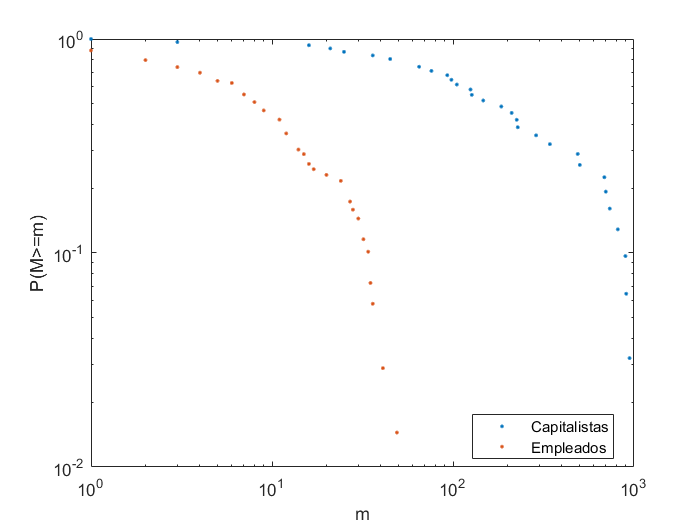

C = agentes([agentes.clase] == 'C');
for ii = 1:length(C)
    y_C(ii) = length(C([C.m] >= C(ii).m))/length(C);
end
E = agentes([agentes.clase] == 'E');
for ii = 1:length(E)
    y_E(ii) = length(E([E.m] >= E(ii).m))/length(E);
end
plot([C.m],y_C,'.',[E.m],y_E,'.')
legend({'Capitalistas','Empleados'},"Location","best")
xlabel('m')
ylabel('P(M>=m)')
set(gca,'xscale','log')
set(gca,'yscale','log')

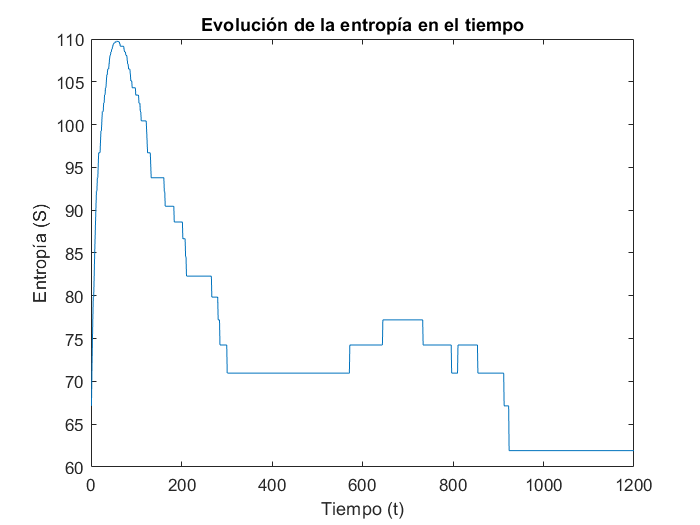

animacionDistribucionesDesagregadas(agentes_t,1)

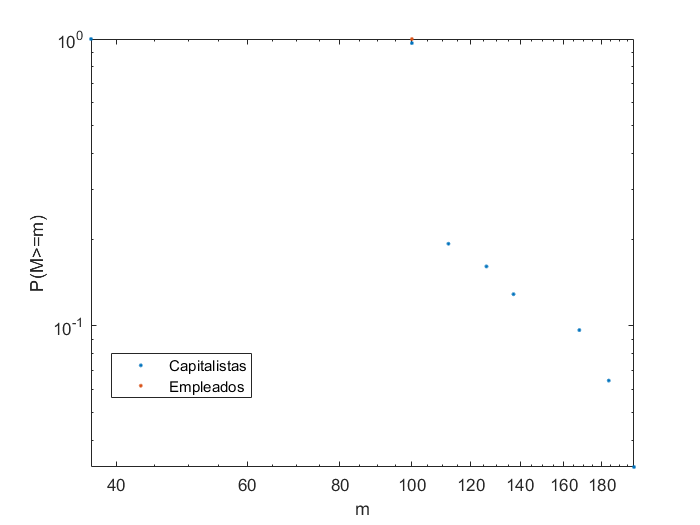

Error using pause
Operation terminated by user

Error in animacionDistribucionesDesagregadas (line 38)
            pause(1/60)

animacionDistribucionesDesagregadas(agentes_t,2)

tic
plotEntropia(agentes_t,false)

toc

Elapsed time is 41.809722 seconds.
